%This is the main body of this computer assignment
clc
clear all

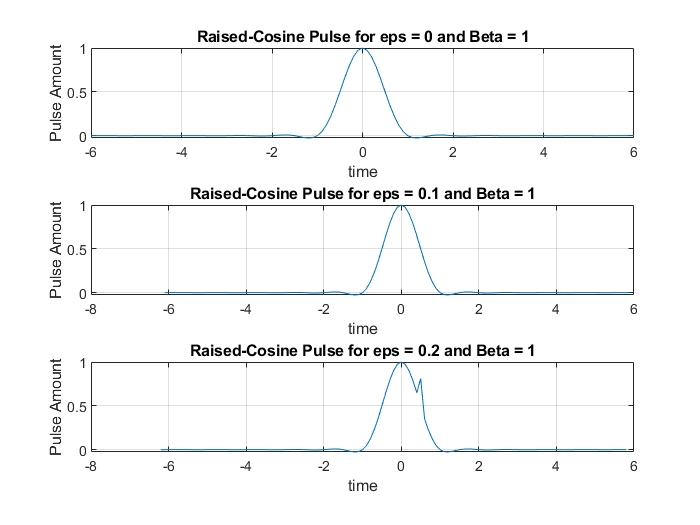

% Plotting of raised-cosine
%In the first part we desire to plot the raised-cosine pulse for different
%scenarios.
T = 1;
Fs = 10;
Beta = 1;
sampling_error  = [0,0.1*T,0.2*T];
[t1 ,Raised_Cosine1] = Raised_Cosine_Pulse(T, Fs, Beta,sampling_error(1));
[t2, Raised_Cosine2] = Raised_Cosine_Pulse(T, Fs, Beta, sampling_error(2));
[t3, Raised_Cosine3] = Raised_Cosine_Pulse(T, Fs, Beta, sampling_error(3));
%Now we continue to plot the raised cosines.
t_arr=[t1 t2 t3];
pulse_arr=[Raised_Cosine1 Raised_Cosine2 Raised_Cosine3];
for i = 1 : 3
    subplot(3,1,i)
    plot (t_arr(1+length(t1)*(i-1):length(t1)*i),pulse_arr(1+length(t1)*(i-1):length(t1)*i))
    title("Raised-Cosine Pulse for eps = "+ sampling_error(i) +" and Beta = " + Beta);
    xlabel('time');
    ylabel('Pulse Amount');
    %xlim([-9 9])
    grid on;
end

%% Transmission signal generation
% Here we shall create the transmission signal as instructed.(The variable
% names are exactly as suggested in the assignment)

N = 10e5;
bits = randi([0,1], 1, N);

modulated_symbols = zeros(1,length(bits));

for i=1:length(bits)
    if ( bits(1,i) == 1 )
        modulated_symbols(1, i) = 1 ;
    else
        modulated_symbols(1, i) = -1;
    end
end
%Here we add zeros between each two consecutive symbols in the modulated
%symbols vector with the help of the hint in the assignment we must pay
%attention that L=T*Fs
temp0 = upsample(modulated_symbols, T*Fs);
temp0 = temp0(1 : (end -(T*Fs - 1)));
%Now we create the transmitted signals with the help of convolution.
transmitted_signal1 = conv(temp0, Raised_Cosine1);
transmitted_signal2 = conv(temp0, Raised_Cosine2);
transmitted_signal3 = conv(temp0, Raised_Cosine3);

%% AWGN channel and noise creation
%Here we shall model the AWGN channel and create noise for it.
%First we define some needed stuff as commanded in the assignment
%description.
Eb = 1;
SNR_dB = 0:10;
SNR = zeros(1,length(SNR_dB)) ;
ETA = zeros(1,length(SNR));

for i=1:length(SNR)
    SNR(1,i) = (10)^(SNR_dB(1,i)/10) ;
end
for i=1:length(ETA)
    ETA(1,i) = Eb/(SNR(1,i)) ;
end
%Here we create the noise, we must pay attention that it doesn't matter
%which transmitted signal length we choose for they are all the same.
Noise = randn(1,length(transmitted_signal1));
Noise = diag(sqrt(ETA./2))*repmat(Noise,11,1);
%Here we define the received signal for the three different roll-off
%factors.
received_signal1 = repmat(transmitted_signal1,11,1)+ Noise;
received_signal2 = repmat(transmitted_signal2,11,1)+ Noise;
received_signal3 = repmat(transmitted_signal3,11,1)+ Noise;

%% Symbol Detection
%Here we shall attempt to detect the symbols.

%With the help of the hint in the assignment description we have(L=T*Fs)
T_sampling = 6*T*Fs + 1 : T*Fs : (N+6-1)*T*Fs + 1;

%Now we create the samples for each of the three different roll-off factors
samples1 = received_signal1(:,T_sampling);
samples2 = received_signal2(:,T_sampling);
samples3 = received_signal3(:,T_sampling);
%Now we detect the symbols with the help of the function we wrote.
detected_symbols1 = Symbol_Detector(N,samples1);
detected_symbols2 = Symbol_Detector(N,samples2);
detected_symbols3 = Symbol_Detector(N,samples3);

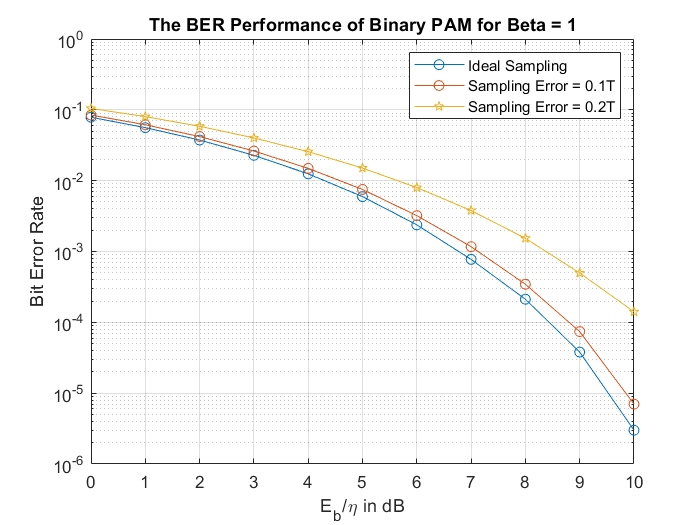

%% Calculating Probability Error and plotting
%Here we shall calcualte the error probability and plot the required
%graphs.
Modulo_Symbols=repmat(modulated_symbols,11,1);
%Here we calculate the number of errors
Number_of_errors1=sum((Modulo_Symbols ~= detected_symbols1),2);
Number_of_errors2=sum((Modulo_Symbols ~= detected_symbols2),2);
Number_of_errors3=sum((Modulo_Symbols ~= detected_symbols3),2);
%Here we calculate the error probability.
PE1=reshape(Number_of_errors1, [1 11])/N;
PE2=reshape(Number_of_errors2, [1 11])/N;
PE3=reshape(Number_of_errors3, [1 11])/N;
%Now we shall continue to the plot.
figure
semilogy(SNR_dB, PE1 ,'-o' ,SNR_dB ,PE2,'-o' ,SNR_dB ,PE3,'-p')
grid on
title("The BER Performance of Binary PAM for Beta = " + Beta)
legend('Ideal Sampling','Sampling Error = 0.1T','Sampling Error = 0.2T')
ylabel('Bit Error Rate')
xlabel('{E_b}/\eta in dB');

%Functions
%In this function we shall design the Raised-Cosine pulse.

function [t , pulse] = Raised_Cosine_Pulse(T,Fs,Beta,sampling_error)
%Here we create t due to the hint in the project description.
t = (-6*T*Fs:6*T*Fs)/Fs-sampling_error;
%we create a pulse array corresponding to the length of t.
pulse = zeros(1,length(t));
%In this loop we generate our raised-cosine and fill our pulse array.
for i = 1 : length(t)
    %Here we check if t=+-T/2Beta or not if so we use the sinc function.
   if ((t(1,i) == -T/(2*Beta)) || ( t(1,i) == T/(2*Beta) ) )
       pulse(1,i) = (pi/4)*sinc(1/(2*Beta));
   else 
       pulse(1,i) = (cos(pi*Beta*t(1,i)/T).*sinc(t(1,i)/T))./((1-(2*Beta.*t(1,i)./T).^2));
   end
end
end

%In this function we shall create a mechanism to detect the symbols.
function detected_symbols = Symbol_Detector(N,samples)
%We first create a matrix for the detected symbols
detected_symbols = zeros(11,N);
%We define the threshold for being positive or negative
POS = samples >= 0;
NEG = samples < 0;
%We assign 1 or -1 to the symbols according to them being positive or
%negative.
detected_symbols(POS) = 1 ;
detected_symbols(NEG) = -1 ;
end
